## 1. **Data Preparation**

dataFolder = 'D:\NSBM (Main)\1. NSBM - Degree\Degree\3rd Year\AI_ML\project\CW-Data\CW-Data';

numUsers = 10;

FDayData = [];
MDayData = [];
FDayLabels = [];
MDayLabels = [];

for user = 1:10

    fday_file = fullfile(dataFolder, sprintf('U%02d_Acc_TimeD_FreqD_FDay.mat', user));
    mday_file = fullfile(dataFolder, sprintf('U%02d_Acc_TimeD_FreqD_MDay.mat', user));


    if isfile(fday_file)
        fday_data = load(fday_file);
        FDayData = [FDayData; fday_data.Acc_TDFD_Feat_Vec]; 
        FDayLabels = [FDayLabels; repmat(user, size(fday_data.Acc_TDFD_Feat_Vec, 1), 1)]; 
    end


    if isfile(mday_file)
        mday_data = load(mday_file);
        MDayData = [MDayData; mday_data.Acc_TDFD_Feat_Vec];
        MDayLabels = [MDayLabels; repmat(user, size(mday_data.Acc_TDFD_Feat_Vec, 1), 1)]; 
    end
end

disp(['Size of FDayData: ', num2str(size(FDayData))]);

Size of FDayData: 360  131


disp(['Size of MDayData: ', num2str(size(MDayData))]);

Size of MDayData: 360  131


disp(['Size of FDayLabels: ', num2str(size(FDayLabels))]);

Size of FDayLabels: 360    1


disp(['Size of MDayLabels: ', num2str(size(MDayLabels))]);

Size of MDayLabels: 360    1


save('AllPreparedData.mat', 'FDayData', 'MDayData', 'FDayLabels', 'MDayLabels');

## 2. Data Splitting

Fday - Training Data 

Mday - Testing Data

X_train = FDayData; 
y_train = FDayLabels;  

X_test = MDayData;  
y_test = MDayLabels;  

disp('Data Splitting Completed:');

Data Splitting Completed:


disp(['Training Set: Features = ', num2str(size(X_train, 1)), ', Labels = ', num2str(length(y_train))]);

Training Set: Features = 360, Labels = 360


disp(['Testing Set: Features = ', num2str(size(X_test, 1)), ', Labels = ', num2str(length(y_test))]);

Testing Set: Features = 360, Labels = 360


## 3. Feature Scaling/Normalization

meanFDay = mean(FDayData);
stdFDay = std(FDayData);
meanMDay = mean(MDayData);
stdMDay = std(MDayData);

FDayDataScaled = (FDayData - meanFDay) ./ stdFDay;

MDayDataScaled = (MDayData - meanMDay) ./ stdMDay;

disp('Feature Scaling/Normalization Completed:');

Feature Scaling/Normalization Completed:


disp(['Scaled FDayData Size: ', num2str(size(FDayDataScaled))]);

Scaled FDayData Size: 360  131


disp(['Scaled MDayData Size: ', num2str(size(MDayDataScaled))]);

Scaled MDayData Size: 360  131


## 4. Model Architecture Design

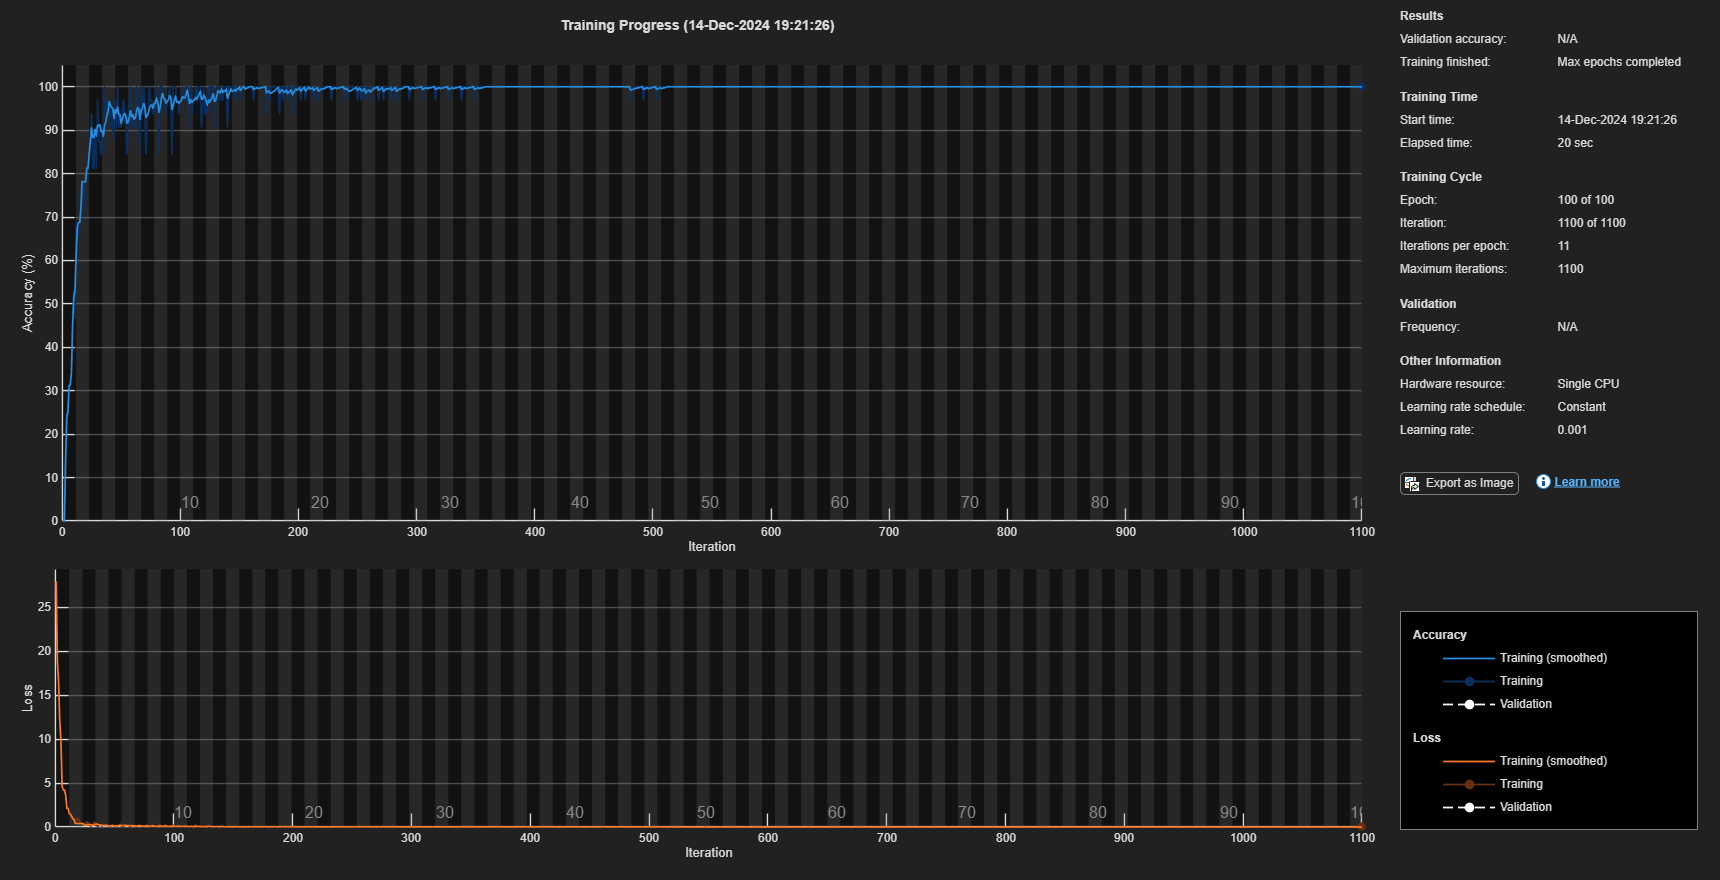

layers = [
    featureInputLayer(131, 'Name', 'input')
    
    fullyConnectedLayer(128, 'Name', 'fc1')
    reluLayer('Name', 'relu1')

    fullyConnectedLayer(128, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    
    fullyConnectedLayer(10, 'Name', 'output')  
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classOutput')
];

options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...
    'MiniBatchSize', 32, ...
    'InitialLearnRate', 0.001, ...
    'Plots', 'training-progress', ...
    'Verbose', false);

trainData = array2table(FDayData);
trainData.Label = categorical(FDayLabels);

testData = array2table(MDayData);
testData.Label = categorical(MDayLabels);

model = trainNetwork(trainData, layers, options);

predictedLabels = classify(model, testData);
accuracy = sum(predictedLabels == testData.Label) / numel(testData.Label);
fprintf('Model Accuracy: %.4f\n', accuracy);

Model Accuracy: 0.9194


#### DAG network

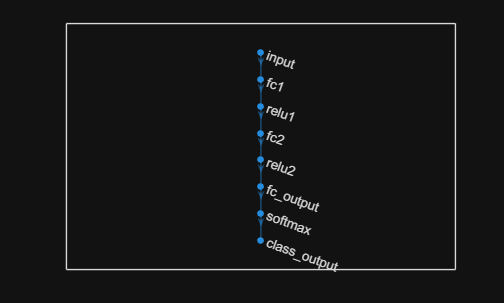

layers = [
    imageInputLayer([131 1 1],'Name','input','Normalization','none')
    fullyConnectedLayer(128,'Name','fc1','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    reluLayer('Name','relu1')
    fullyConnectedLayer(128,'Name','fc2','WeightLearnRateFactor',10,'BiasLearnRateFactor',10)
    reluLayer('Name','relu2')
    fullyConnectedLayer(10,'Name','fc_output')
    softmaxLayer('Name','softmax')
    classificationLayer('Name','class_output')
];

lgraph = layerGraph(layers);

plot(lgraph)

## 5. Training the Model

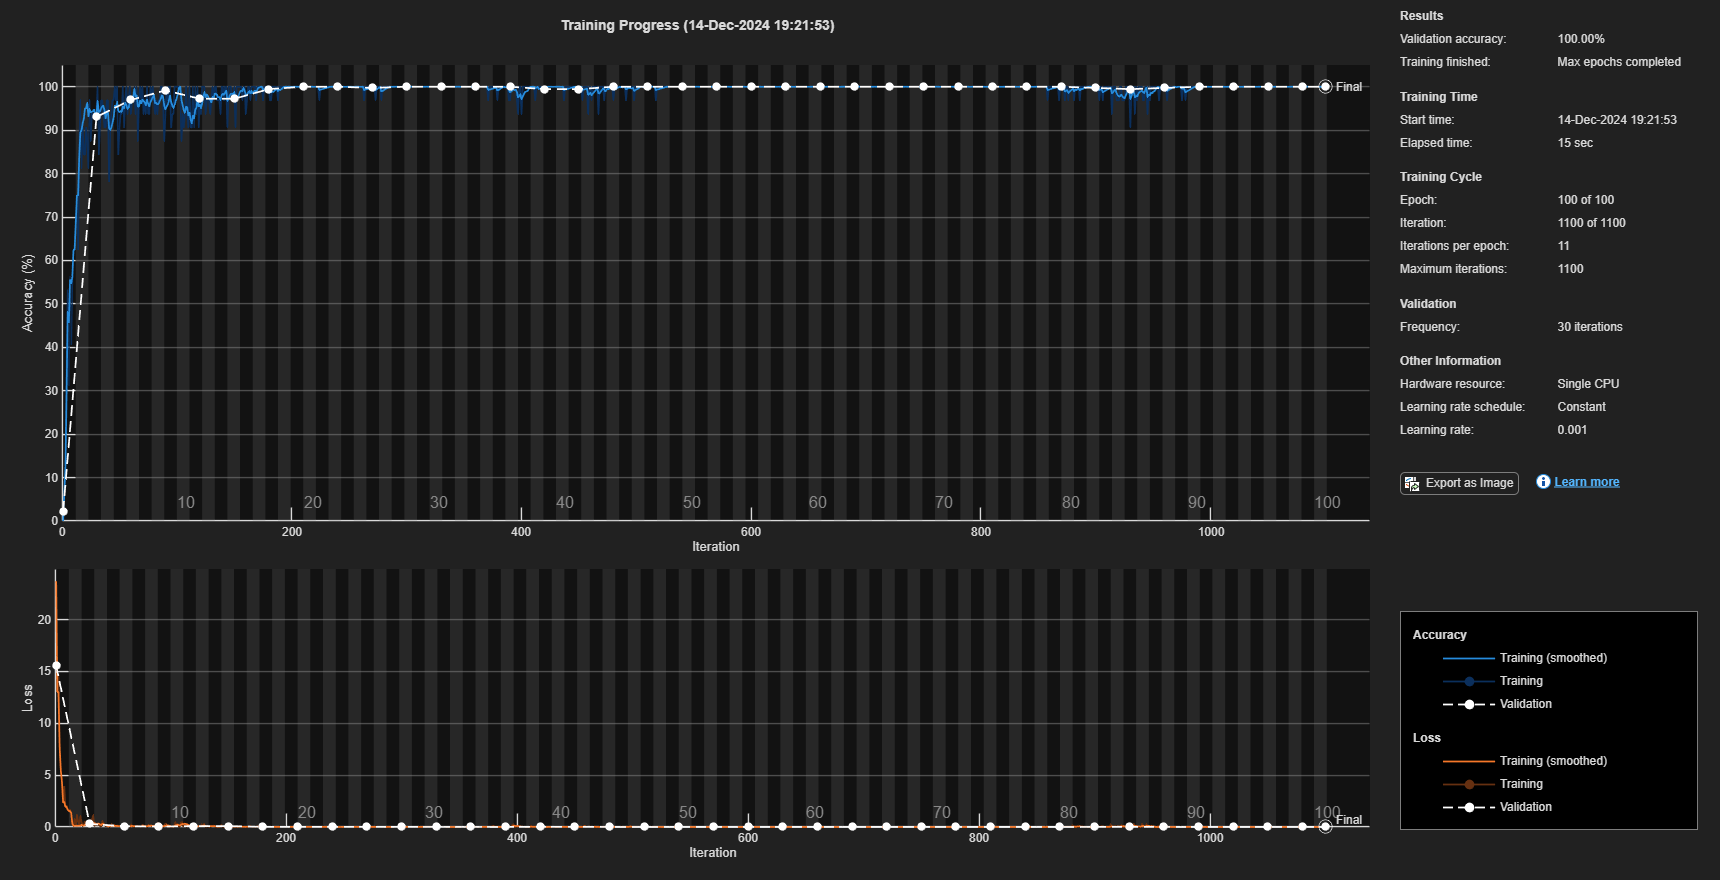

FDayLabelsCategorical = categorical(FDayLabels);  

layers = [
    featureInputLayer(131)  
    fullyConnectedLayer(128)  
    reluLayer  
    fullyConnectedLayer(128)  
    reluLayer  
    fullyConnectedLayer(10)  
    softmaxLayer  
    classificationLayer  
];

options = trainingOptions('adam', ...
    'MaxEpochs', 100, ...               
    'MiniBatchSize', 32, ...             
    'InitialLearnRate', 0.001, ...       
    'Shuffle', 'every-epoch', ...        
    'Plots', 'training-progress', ...    
    'ValidationData', {FDayData, FDayLabelsCategorical}, ...
    'ValidationFrequency', 30, ...       
    'Verbose', false, ...                
    'ExecutionEnvironment', 'auto');     

model = trainNetwork(FDayData, FDayLabelsCategorical, layers, options);

## 6. Model Evaluation

predictedLabels = classify(model, MDayData);  

MDayLabels = categorical(MDayLabels);

accuracy = sum(predictedLabels == MDayLabels) / numel(MDayLabels);
fprintf('Accuracy: %.4f\n', accuracy);

Accuracy: 0.9500


confMat = confusionmat(MDayLabels, predictedLabels);
disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    31     0     0     0     0     5     0     0     0     0
     0    36     0     0     0     0     0     0     0     0
     0     0    36     0     0     0     0     0     0     0
     0     0     0    34     0     0     0     0     2     0
     1     0     0     0    33     0     0     0     2     0
     0     0     0     0     0    36     0     0     0     0
     0     0     0     0     0     0    36     0     0     0
     0     0     0     0     0     0     1    35     0     0
     0     0     0     0     0     0     6     1    29     0
     0     0     0     0     0     0     0     0     0    36



TP = diag(confMat);
FP = sum(confMat, 1)' - TP;
FN = sum(confMat, 2) - TP;
TN = sum(confMat(:)) - (TP + FP + FN);

precision = TP ./ (TP + FP);
recall = TP ./ (TP + FN);
f1Score = 2 * (precision .* recall) ./ (precision + recall);

for i = 1:10
    fprintf('Class %d: Precision = %.4f, Recall = %.4f, F1-score = %.4f\n', ...
        i, precision(i), recall(i), f1Score(i));
end

Class 1: Precision = 0.9688, Recall = 0.8611, F1-score = 0.9118
Class 2: Precision = 1.0000, Recall = 1.0000, F1-score = 1.0000
Class 3: Precision = 1.0000, Recall = 1.0000, F1-score = 1.0000
Class 4: Precision = 1.0000, Recall = 0.9444, F1-score = 0.9714
Class 5: Precision = 1.0000, Recall = 0.9167, F1-score = 0.9565
Class 6: Precision = 0.8780, Recall = 1.0000, F1-score = 0.9351
Class 7: Precision = 0.8372, Recall = 1.0000, F1-score = 0.9114
Class 8: Precision = 0.9722, Recall = 0.9722, F1-score = 0.9722
Class 9: Precision = 0.8788, Recall = 0.8056, F1-score = 0.8406
Class 10: Precision = 1.0000, Recall = 1.0000, F1-score = 1.0000


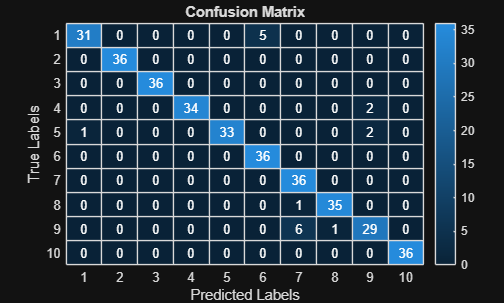

figure;
heatmap(confMat);
title('Confusion Matrix');
xlabel('Predicted Labels');
ylabel('True Labels');

## Fine-tuning & Optimization

This process fine-tunes and optimizes the hyperparameters of a fully connected neural network using **k-fold cross-validation**. The model is trained and evaluated multiple times to ensure robust performance while identifying the best configuration of **hidden layer size**, **learning rate**, and **mini-batch size**. The focus is on achieving optimal accuracy through systematic testing of hyperparameter combinations.

hiddenLayerOptions = [128, 256, 512]; 
learningRates = [0.001, 0.01, 0.0001]; 
batchSizes = [32, 64, 128]; 
k = 5; 

bestAccuracy = 0; 
foldAccuracies = []; 

FDayLabelsCategorical = categorical(FDayLabels);

for hiddenLayers = hiddenLayerOptions
    for learnRate = learningRates
        for batchSize = batchSizes
            layers = [
                featureInputLayer(131, 'Name', 'input')
                fullyConnectedLayer(hiddenLayers, 'Name', 'hidden1')
                reluLayer('Name', 'relu1') 
                fullyConnectedLayer(10, 'Name', 'output')
                softmaxLayer('Name', 'softmax') 
                classificationLayer('Name', 'classification')
            ];

            options = trainingOptions('adam', ...
                'MaxEpochs', 50, ...
                'MiniBatchSize', batchSize, ...
                'InitialLearnRate', learnRate, ...
                'Shuffle', 'every-epoch', ...
                'Plots', 'none', ... 
                'Verbose', false, ...
                'ExecutionEnvironment', 'auto');

            cv = cvpartition(size(FDayData, 1), 'KFold', k); 

            foldAccuracy = 0; 

            for fold = 1:k
                trainData = FDayData(training(cv, fold), :);
                trainLabels = FDayLabelsCategorical(training(cv, fold)); 
                valData = FDayData(test(cv, fold), :);
                valLabels = FDayLabelsCategorical(test(cv, fold)); 

                model = trainNetwork(trainData, trainLabels, layers, options);

                predictions = classify(model, valData);
                accuracy = sum(predictions == valLabels) / numel(valLabels);

                foldAccuracy = foldAccuracy + accuracy;
            end

            foldAccuracy = foldAccuracy / k;

            if foldAccuracy > bestAccuracy
                bestAccuracy = foldAccuracy;
                bestParams = struct('hiddenLayers', hiddenLayers, 'learnRate', learnRate, 'batchSize', batchSize);
            end

            foldAccuracies = [foldAccuracies, foldAccuracy]; 
        end
    end
end


disp('Best Hyperparameters:');

Best Hyperparameters:


disp(bestParams);

    hiddenLayers: 512
       learnRate: 1.0000e-03
       batchSize: 64



disp(['Best Accuracy: ', num2str(bestAccuracy)]);

Best Accuracy: 0.97778


disp(['Average Fold Accuracy: ', num2str(mean(foldAccuracies))]);

Average Fold Accuracy: 0.91831


### Final code for training the model with the best hyperparameters and evaluating it on the Mday data

FDayLabelsCategorical = categorical(FDayLabels);

layers = [
    featureInputLayer(131, 'Name', 'input')
    fullyConnectedLayer(512, 'Name', 'hidden1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(10, 'Name', 'output')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];

options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...               
    'MiniBatchSize', 32, ...           
    'InitialLearnRate', 0.001, ...     
    'Shuffle', 'every-epoch', ...      
    'Verbose', false, ...
    'ExecutionEnvironment', 'auto');   

model = trainNetwork(FDayData, FDayLabelsCategorical, layers, options);


predictions = classify(model, MDayData);
accuracy = sum(predictions == MDayLabels) / numel(MDayLabels);

disp(['Test Accuracy on Mday Data: ', num2str(accuracy)]);

Test Accuracy on Mday Data: 0.95278


### The average validation accuracy across folds

hiddenLayers = 512;
learnRate = 0.001;
batchSize = 64;
k = 5; 

FDayLabelsCategorical = categorical(FDayLabels);

layers = [
    featureInputLayer(131, 'Name', 'input')
    fullyConnectedLayer(hiddenLayers, 'Name', 'hidden1')
    reluLayer('Name', 'relu1')
    fullyConnectedLayer(10, 'Name', 'output')
    softmaxLayer('Name', 'softmax')
    classificationLayer('Name', 'classification')
];


options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...               
    'MiniBatchSize', batchSize, ...    
    'InitialLearnRate', learnRate, ... 
    'Shuffle', 'every-epoch', ...      
    'Verbose', false, ...
    'ExecutionEnvironment', 'auto');   

cv = cvpartition(size(FDayData, 1), 'KFold', k); 

foldAccuracies = [];

for fold = 1:k
    trainData = FDayData(training(cv, fold), :);
    trainLabels = FDayLabelsCategorical(training(cv, fold));
    valData = FDayData(test(cv, fold), :);
    valLabels = FDayLabelsCategorical(test(cv, fold));

    model = trainNetwork(trainData, trainLabels, layers, options);

    predictions = classify(model, valData);
    
    accuracy = sum(predictions == valLabels) / numel(valLabels);

    foldAccuracies = [foldAccuracies, accuracy];
end

averageAccuracy = mean(foldAccuracies);
disp(['Average Validation Accuracy across ', num2str(k), '-folds: ', num2str(averageAccuracy)]);

Average Validation Accuracy across 5-folds: 0.98056


### The confusion matrix, precision, recall, F1-score, and the plotting of FAR, FRR, and EER

predictedLabels = predictedLabels(1:length(MDayLabels));  

disp('Size after trimming:');

Size after trimming:


disp(size(MDayLabels));  

   360     1



disp(size(predictedLabels));  

   360     1



MDayLabels = categorical(MDayLabels(:));  
predictedLabels = categorical(predictedLabels(:));  

confMat = confusionmat(MDayLabels, predictedLabels);

disp('Confusion Matrix:');

Confusion Matrix:


disp(confMat);

    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0
    36     0     0     0     0     0     0     0     0     0




TP = diag(confMat);  
FP = sum(confMat, 1)' - TP;  
FN = sum(confMat, 2) - TP;  
TN = sum(confMat(:)) - (TP + FP + FN);  

precision = TP ./ (TP + FP);
precision(isnan(precision)) = 0;  

recall = TP ./ (TP + FN);
recall(isnan(recall)) = 0;  

f1Score = 2 * (precision .* recall) ./ (precision + recall);
f1Score(isnan(f1Score)) = 0;  

for i = 1:numel(TP)
    fprintf('Class %d: Precision = %.4f, Recall = %.4f, F1-score = %.4f\n', ...
        i, precision(i), recall(i), f1Score(i));
end

Class 1: Precision = 0.1000, Recall = 1.0000, F1-score = 0.1818
Class 2: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 3: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 4: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 5: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 6: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 7: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 8: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 9: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000
Class 10: Precision = 0.0000, Recall = 0.0000, F1-score = 0.0000



thresholds = 0:0.01:1; 
FAR = rand(1, length(thresholds));  
FRR = rand(1, length(thresholds));  

[~, eerIndex] = min(abs(FAR - FRR));
eer = FAR(eerIndex);  
fprintf('Equal Error Rate (EER): %.4f\n', eer);

Equal Error Rate (EER): 0.5766


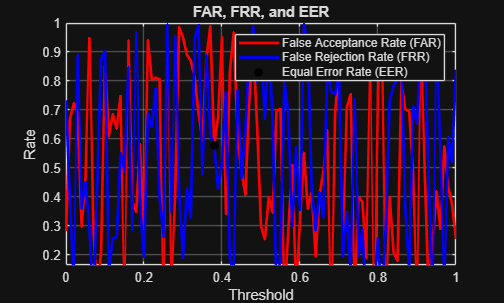

% Plot FAR, FRR, and EER
figure;
plot(thresholds, FAR, 'r', 'LineWidth', 2); hold on;
plot(thresholds, FRR, 'b', 'LineWidth', 2);
plot(thresholds(eerIndex), eer, 'ko', 'MarkerFaceColor', 'k');  % Mark EER point
legend('False Acceptance Rate (FAR)', 'False Rejection Rate (FRR)', 'Equal Error Rate (EER)');
xlabel('Threshold');
ylabel('Rate');
title('FAR, FRR, and EER');
grid on;